# Taller 1, punto 5: Dataset_train_test modificado para banknote

Es el mismo procedimiento del script Dataset_train_test, pero sobre el archivo data_banknote_authentication.txt. Son 1372 billetes con 4 atributos sacados de la transformada wavelet de la imagen (varianza, asimetria, curtosis y entropia) y la clase: 0 = autentico, 1 = falso.

clear; close all; clc

datos = load('data_banknote_authentication.txt');
No_examples = size(datos, 1);
fprintf('Banknote: %d ejemplos, %d atributos\n', No_examples, size(datos, 2) - 1);

Banknote: 1372 ejemplos, 4 atributos


fprintf('Clase 0: %d | Clase 1: %d\n', sum(datos(:,5) == 0), sum(datos(:,5) == 1));

Clase 0: 762 | Clase 1: 610


## Un vistazo rapido a las variables

Las cuatro estan en escalas distintas, asi que despues toca escalarlas.

disp(table({'varianza'; 'asimetria'; 'curtosis'; 'entropia'}, ...
     min(datos(:,1:4))', max(datos(:,1:4))', mean(datos(:,1:4))', std(datos(:,1:4))', ...
     'VariableNames', {'Atributo', 'Min', 'Max', 'Media', 'Desv'}))

      Atributo         Min       Max       Media      Desv 
    _____________    _______    ______    _______    ______

    {'varianza' }    -7.0421    6.8248    0.43374    2.8428
    {'asimetria'}    -13.773    12.952     1.9224     5.869
    {'curtosis' }    -5.2861    17.927     1.3976      4.31
    {'entropia' }    -8.5482    2.4495    -1.1917     2.101



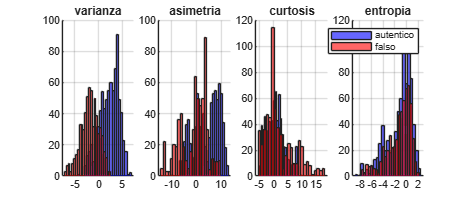


figure('Position', [100 100 900 380]);
nombres = {'varianza', 'asimetria', 'curtosis', 'entropia'};
for j = 1:4
    subplot(1, 4, j); hold on
    histogram(datos(datos(:,5) == 0, j), 25, 'FaceColor', 'b');
    histogram(datos(datos(:,5) == 1, j), 25, 'FaceColor', 'r');
    title(nombres{j}); grid on
end
legend('autentico', 'falso');
guardar_fig('banknote_histogramas');

## Se mezcla con semilla fija

rng(2021)
ind = randperm(No_examples);

## Division 60-40, 70-30, 80-20 y 90-10

Aqui si hace falta el round, porque 0.9 * 1372 = 1234.8 y no se puede indexar con eso.

proporciones = [0.6 0.7 0.8 0.9];
S = struct([]);
for k = 1:numel(proporciones)
    p = proporciones(k);
    n_train = round(p * No_examples);

    S(k).p   = p;
    S(k).Xtr = datos(ind(1:n_train), 1:4);
    S(k).ytr = datos(ind(1:n_train), 5);
    S(k).Xte = datos(ind(n_train+1:end), 1:4);
    S(k).yte = datos(ind(n_train+1:end), 5);

    fprintf('%d-%d : %4d de entrenamiento (%.1f%% falsos), %3d de test (%.1f%% falsos)\n', ...
        round(100*p), round(100*(1-p)), n_train, 100*mean(S(k).ytr), ...
        No_examples - n_train, 100*mean(S(k).yte));
end

60-40 :  823 de entrenamiento (45.0% falsos), 549 de test (43.7% falsos)
70-30 :  960 de entrenamiento (44.1% falsos), 412 de test (45.4% falsos)
80-20 : 1098 de entrenamiento (44.0% falsos), 274 de test (46.4% falsos)
90-10 : 1235 de entrenamiento (44.1% falsos), 137 de test (47.4% falsos)


## Se guardan las particiones

save('banknote_splits.mat', 'S');
disp('Particiones guardadas en banknote_splits.mat')

Particiones guardadas en banknote_splits.mat
